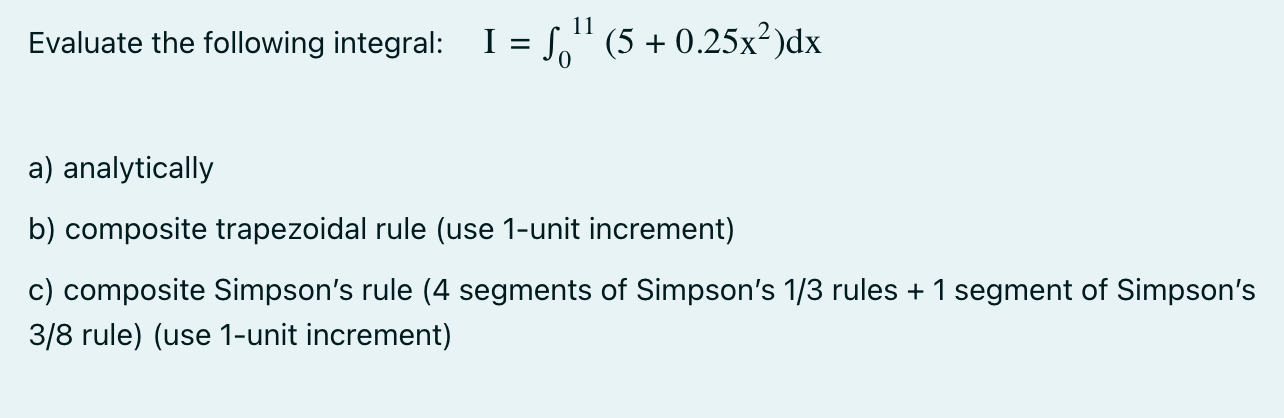

f = @(x) 5 + 0.25 .* x.^2;

a = 0;
b = 11;

p = [0.25 0 5];
q = polyint(p);

Itrue = diff(polyval(q, [a b]))

Itrue = 165.9167

ns = 11;
I_trap = trap(f, a, b, ns)

I_trap = 166.3750

ns = 4;
x = linspace(0, 8, 2 * ns + 1);
y = f(x);

h = (8 - 0) / (ns * 2);

for i = 1:ns
    il = 2 * (i - 1) + 1;
    ir = 2 * i + 1;
    simp13(i) = (h / 3) * (y(il) + (4 * y(il + 1)) + y(ir));
end

I_simp13 = sum(simp13);

ns = 6;

x = linspace(8, 11, 3*ns+1);
y = f(x);

h = (11 - 8) / (ns * 3);

for i = 1:ns
    il = 3 * (i - 1) + 1;
    ir = 3 * i + 1;
    simp38(i) = (((3 * h) / 8) * (y(il) + (3 * y(il + 1) + (3 * y(il + 2)) + y(ir))));
end
I_simp38 = sum(simp38);


I_simp = I_simp13 + I_simp38

I_simp = 165.9167